# Basic Trend Visualizations

## Import the data

filename = 'premier-league-matches.csv';
M = readtable(filename);

## Percentage Draw over time

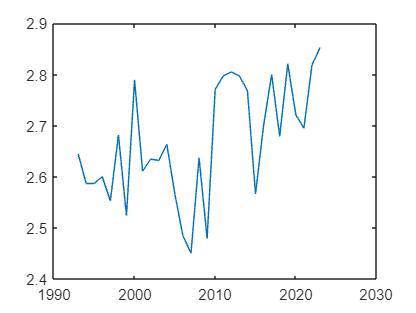

D = []; H = []; A = []; Y = []; TotalGoals = [];
for yr = min(M.Season_End_Year):max(M.Season_End_Year)
    idx = M.Season_End_Year == yr;
    season = M(idx,:);
    Y = [Y, yr];

    % Finding draws, homewins and awaywins
    draws = 0;home=0;away=0;
    for i = 1:length(season.FTR)
        if season.FTR{i} == "D"
            draws = draws + 1;
        elseif season.FTR{i} == "H"
            home = home + 1;
        elseif season.FTR{i} == "A"
            away = away + 1;
        end
    end
    D = [D, draws * 100 / length(season.FTR)];
    H = [H, home * 100 / length(season.FTR)];
    A = [A, away * 100 / length(season.FTR)];
    % computing goals
    TotalGoals = [TotalGoals, (sum(season.HomeGoals)+sum(season.AwayGoals))/length(season.FTR)];
end

figure(1)
plot(Y, TotalGoals)
hold off

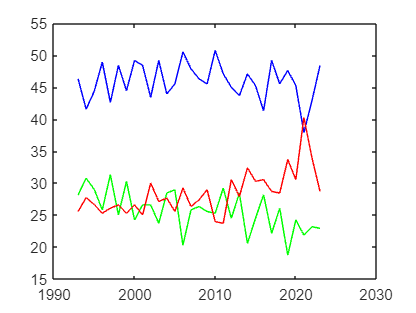

figure(2)
plot(Y, D, 'g')
hold on
plot(Y, H, 'b')
hold on
plot(Y, A, 'r')
hold off